# Examen RA3L - Matlab Partie 2 - Janvier 2025

% Nom :      Guennaoui                                       /10
% Prénom : Fouzi
% Matricule : 22300

Le fichier NewFile3.csv contient les données de tension U et de courant I (sur 12 périodes complète pour les 2 signaux), grandeurs d'une charge inductive compensée par une charge capacitive. L'ensemble de la charge est alimenté en tension alternative, qui oscille à 50 Hz. Le fait de compenser la charge inductive introduit une harmonique de rang 9 dans le signal de courant.

**1) **Les données csv (et non .mat !!) sont déjà chargées via les lignes de code implémentées ci-dessous. **Déterminer la fréquence (Fs) et la période d'échantillonage (Ts) afin de reconstruire le vecteur temporel. Visualiser ensuite la tension U et le courant I en fonction du temps. ***( /1 point)*

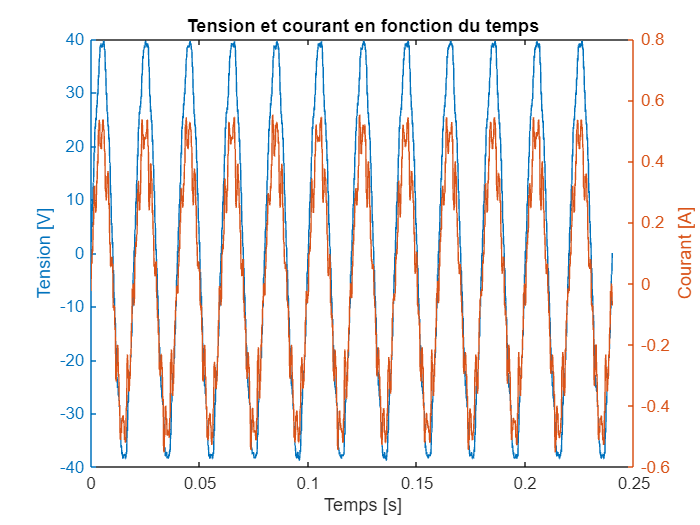

clear all
close all

% Début des lignes de code déjà présentes pour charger le ficher CSV
M=readtable("NewFile3.csv");
M=M{:,varfun(@isnumeric,M,'OutputFormat','uniform')};
U=M(:,1);
I=M(:,2);
% Fin des lignes de code déjà présentes pour charger le ficher CSV
T=1/50; %Une période en 0.02s
tt = 12*T; %12 périodes en 0.24s

t = linspace(0,tt,1200);
figure;
yyaxis left;
plot(t,U); ylabel('Tension [V]'); xlabel("Temps [s]");
yyaxis right; 
plot(t,I); ylabel('Courant [A]'); title('Tension et courant en fonction du temps'); hold off

Ts = mode(diff(t));
Fs=1/Ts;
%code



Résultat attendu :

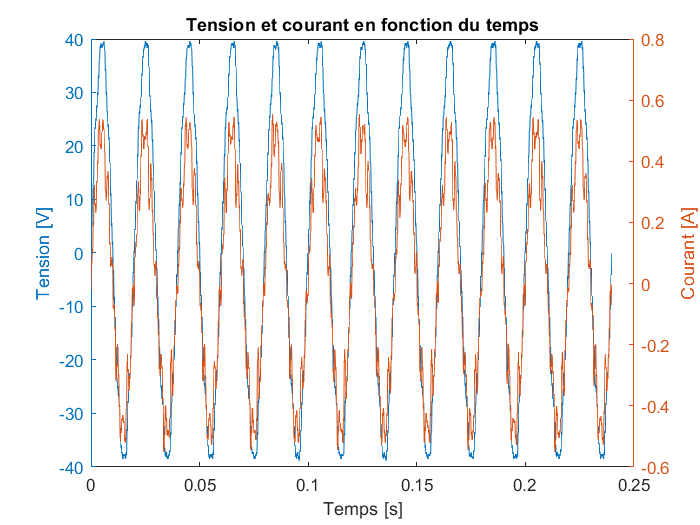

**2) Implémenter le code permettant d'appliquer la FFT sur le signal de courant** **en justifiant chaque étape ****sur feuille annexe****.*** ( /2.5 points)*

NB : Sans justification sur papier, le code ne rapportera aucun point. 

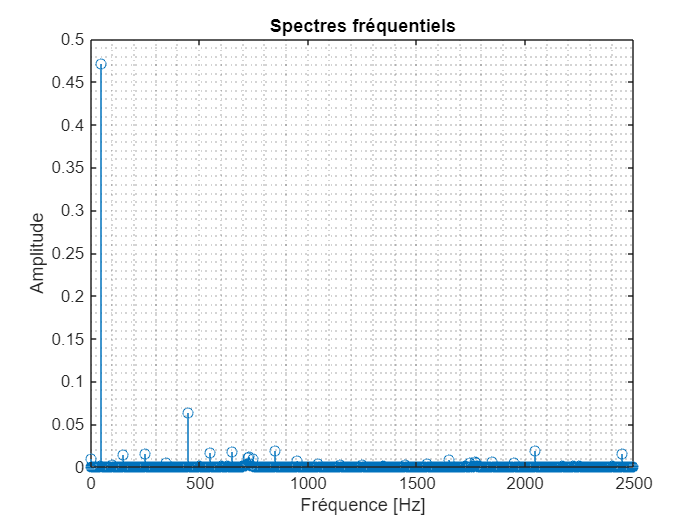

%code
N = length(t);
X=fft(I);
Amp = abs(X)/N; 
Amp=Amp(1:N/2+1); 
Amp(2:end) = Amp(2:end)*2;
n=0:1:N/2;
dF=Fs/N;
f=n*dF;

figure;
stem(f,Amp); xlabel('Fréquence [Hz]'); ylabel("Amplitude"); title("Spectres fréquentiels"); grid minor;

Résultat attendu : 

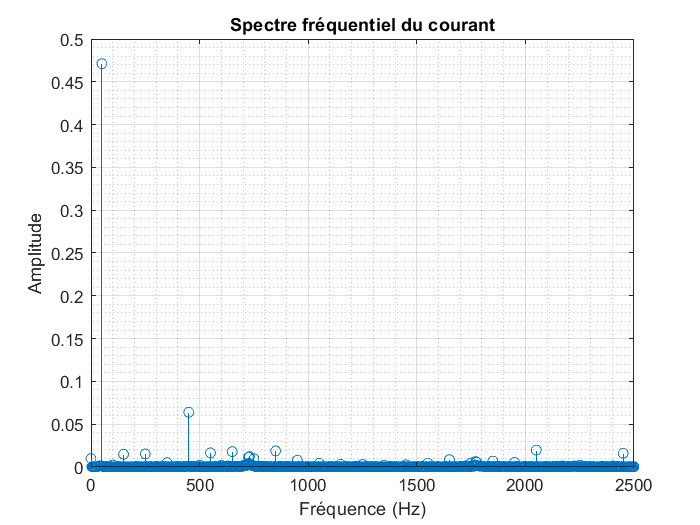

**3) Appliquer un filtre passe-bas, caractérisisé mathématiquement par la fonction de transfert H(s) (ci-dessous), au signal de courant I dont la fréquence de coupure **$\omega_{c\;}$** permet de réduire les fréquences supérieures à 500 Hz (**$\omega_{c\;} =2\pi *500$** rad/s) avec un coefficient d'amortissement **$\xi$ à 0.8 ($\left.\xi =0\ldotp 8\right)$**. **


$$H\left(s\right)=\frac{1}{\left(\frac{s^2 }{\omega_c^2 \;}+\frac{2s\xi }{\omega {\;}_c }+1\right)}$$


**Afficher le signal de sortie **(à stocker dans la variable Y)** et le signal d'entrée de ce filtre sur le même graphique. ***( /1 points)*

%code
s = tf('s');
w = 2*pi*500;
xi = 0.8;

H = 1/( s^2/w^2 + 2*s*xi/w +1 );
minreal(H)

ans =
 
         9.87e06
  ----------------------
  s^2 + 5027 s + 9.87e06
 
Continuous-time transfer function.
Model Properties


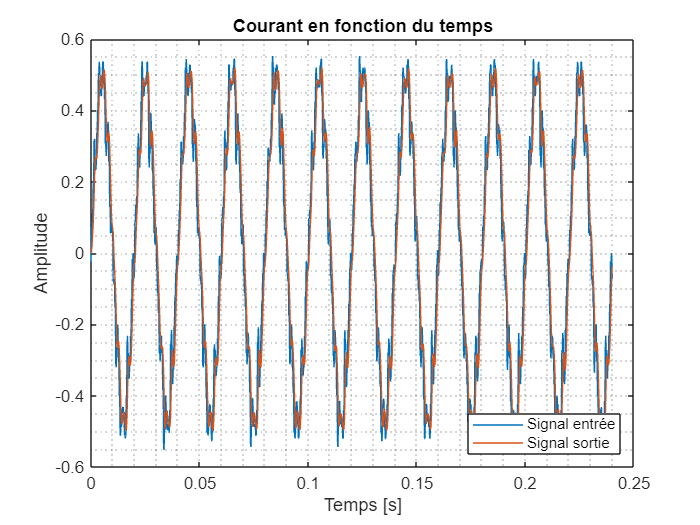

y = lsim(H,I,t);
plot(t,I,t,y); legend("Signal entrée","Signal sortie", "Location","southeast"); ylabel('Amplitude'); xlabel("Temps [s]"); title("Courant en fonction du temps"); grid minor;

Résultat attendu :

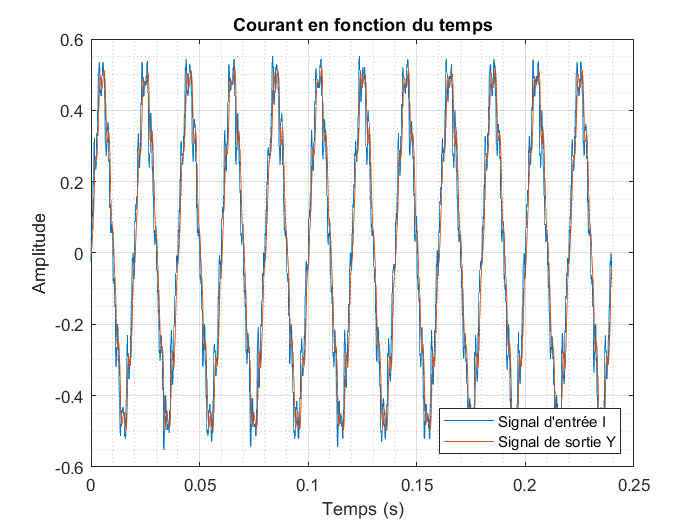

**4) Implémenter à nouveau le code permettant d'appliquer la FFT sur le signal de courant en sortie de filtre ****en travaillant avec une résolution fréquentielle de 25 Hz****. ***( /0.5 points)*

%code
dF2 = 25;
N2=floor(Fs/dF2);
X2=fft(y,N2);
Amp2 = abs(X2)/N2; 
Amp2=Amp2(1:N2/2+1); 

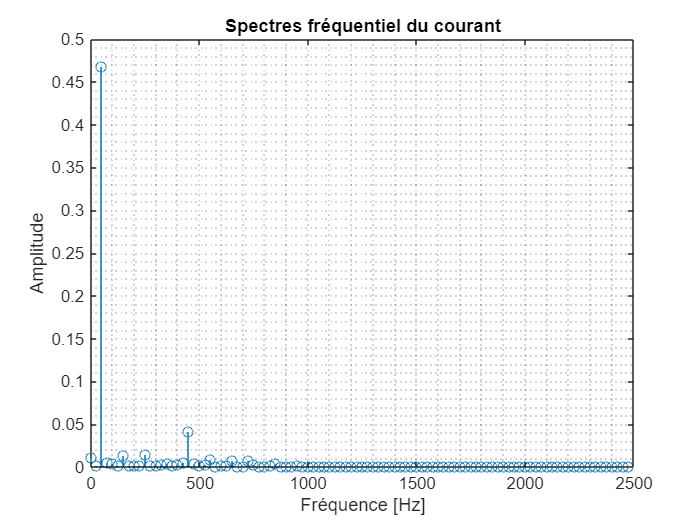

Amp2(2:end) = Amp2(2:end)*2;
n2=0:1:N2/2;
f2=n2*dF2;
figure;
stem(f2,Amp2); xlabel('Fréquence [Hz]'); ylabel("Amplitude"); title("Spectres fréquentiel du courant"); grid minor;

Résultat attendu : 

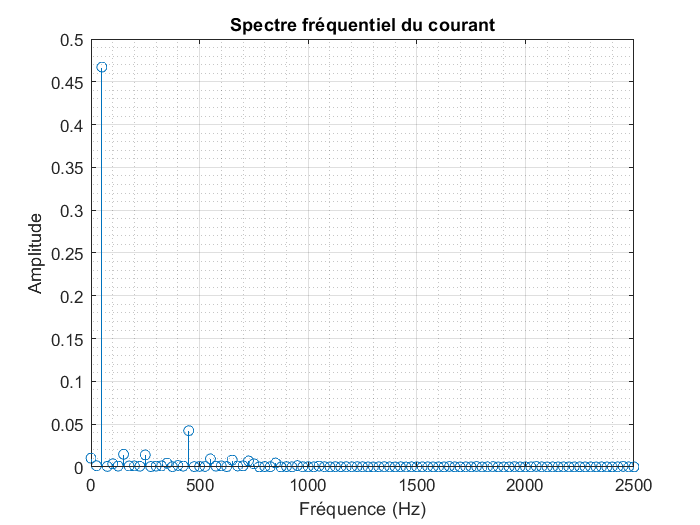

**5) Comment interpréter les résultats obtenus aux questions 2 et 4 sachant que les amplitudes inférieures à 0.05 ne sont pas pertinentes ? Justifier, ****sur feuille annexe****, avec du texte et/ou avec un/des schémas. ***( /2.5 points)*

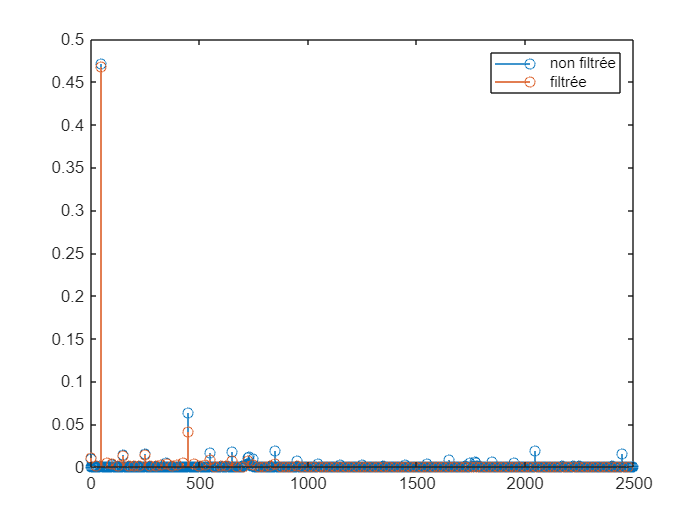

%Pour se faire je supperpose les deux graphs
stem(f,Amp); hold on; stem(f2,Amp2); legend("non filtrée","filtrée");hold off;

**6) Afficher le diagramme de bode du filtre passe-bas, ainsi que les fréquences pour lesquelles le système a été sollicité.**

**Vérifier que le gain obtenu via le diagramme de bode est proche de celui obtenu via l'analyse fréquentielle des signaux en entrée et en sortie du filtre. ***( /1.5 points)*

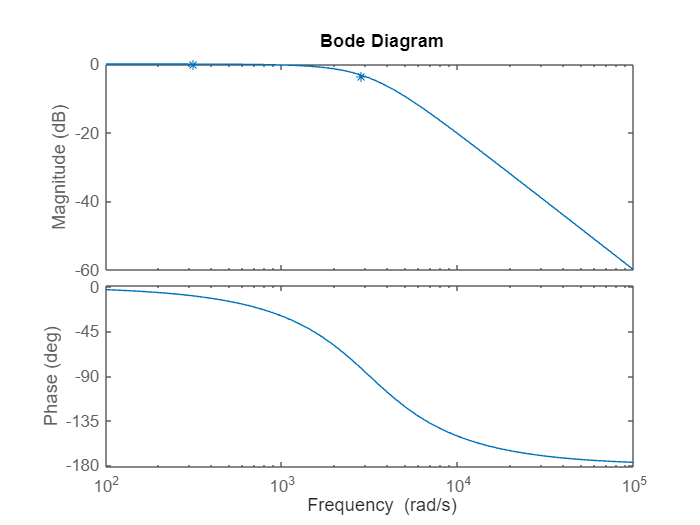

f3 = f(Amp>0.05);
%code
Amp11 = Amp(Amp>0.05);
f11 = f(Amp>0.05);
Amp22 = Amp2(Amp2>0.025);
f22 = f2(Amp2>0.025);
%Diagramme de Bode avec le gain (les deux méthodes marchent, ce code ne fait que montrer que le gain est proche de celui obtenu par l'analyse fréquentielle)
Gain1 = 20*log10([Amp22(1)/Amp11(1)]);
Gain2 = 20*log10([Amp22(2)/Amp11(2)]);
Gain = [Gain1 Gain2];
w = 2*pi*f3(1:2);
semilogx(w,Gain,'*'); hold on; bode(H); hold off

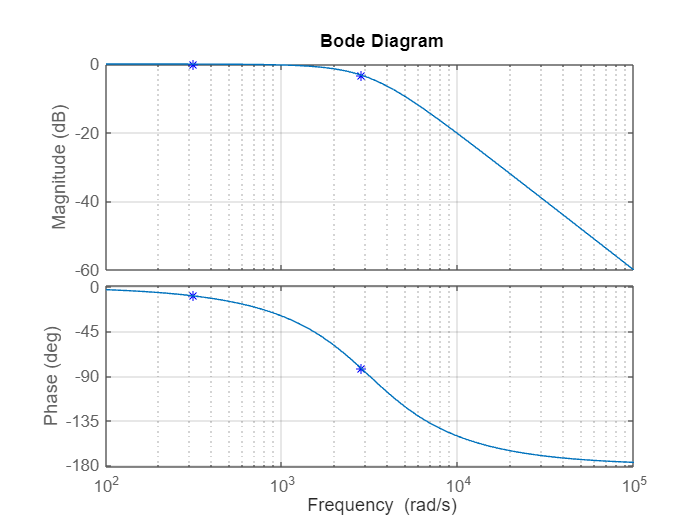

% Diagramme de Bode
w1 = 2*pi*f3(1);
w2 = 2*pi*f3(2);
w = [w1 w2];
bode(H,w,'*'); hold on; bode(H); grid on; hold off; %on a bel et bien un gain de presque 0 et de -3

Résultat attendu :

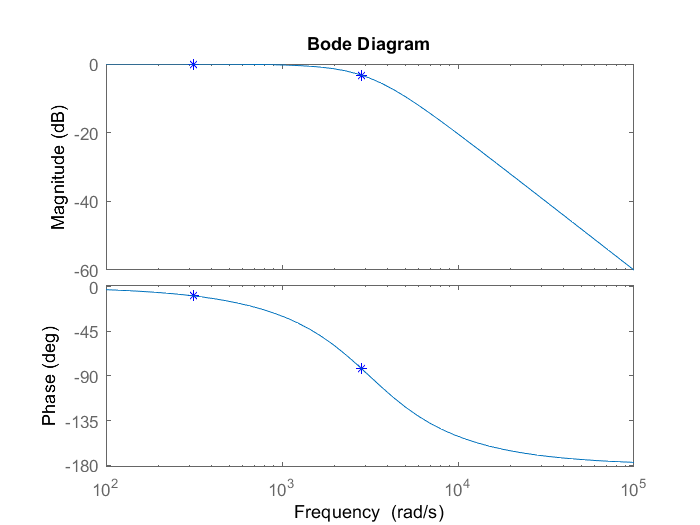

**7) ****Sur feuille annexe****, expliquer pourquoi il y a un décalage temporel entre l'entrée et la sortie du filtre sur base des résultats obtenus aux questions 3 et 6. ***( /1 points)*

NB : il est conseillé d'utiliser Matlab pour vous aider à répondre à cette question sur papier. 

%code
[amp, phase] = bode(H,w)

amp = amp(:,:,1) =

    0.9972


amp(:,:,2) =

    0.6890


phase = phase(:,:,1) =

   -9.1729


phase(:,:,2) =

  -82.4246
